# Creation of Solid Geometry Surface Models for 3D-Printing, Shape Optimization, Topology Optimization (PDE-Toolbox), and Dynamic Simulation (Simscape Multi-Body)

# Part C - Checking, Writing, and Reading Solid Geometries

**Tim Lueth - Professor at Technical Universiity of Munich - Germany - 2019**

**Set Java Heap to 2048 MByte**

## 4 Check, Export and Import of Solid Geometries

### 4.1 Checking Geometries regarding 'non manifold Problems' and 'watertight surfaces'

#### 4.1.1 Check Geometries inside of SG Coder Language


OPEN BOUNDARY:
0 open boundary groups
0 open boundary edges
NON MANIFOLD EGDES:
0 non manifold edges
0 faces over non manifold edges
NON MANIFOLD VERTICES:
1 independent surfaces
0 non manifold vertices
0 faces over non manifold vertices
SELF INTERSECTING FACETS:
too many facets for a self-intersection check
PRESS RETURN AFTER VISUAL CHECK


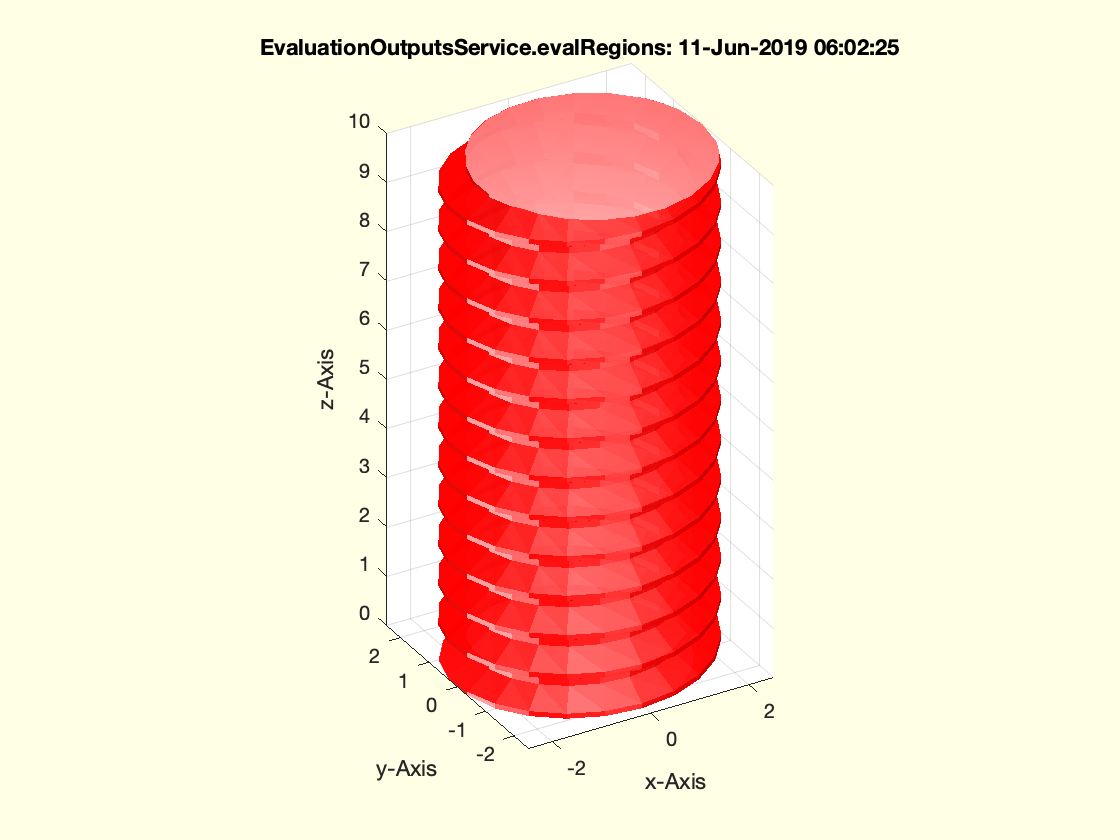


SGofCPLcommand('scr 5 10,  check')



ans = struct with fields:
    VL: [1529×3 double]
    FL: [3054×3 double]


SGofCPLcommand('scr 5 10,  check')


OPEN BOUNDARY:
0 open boundary groups
0 open boundary edges
NON MANIFOLD EGDES:
0 non manifold edges
0 faces over non manifold edges
NON MANIFOLD VERTICES:
2 independent surfaces
20 non manifold vertices
116 faces over non manifold vertices
SELF INTERSECTING FACETS:
too many facets for a self-intersection check
PRESS RETURN AFTER VISUAL CHECK


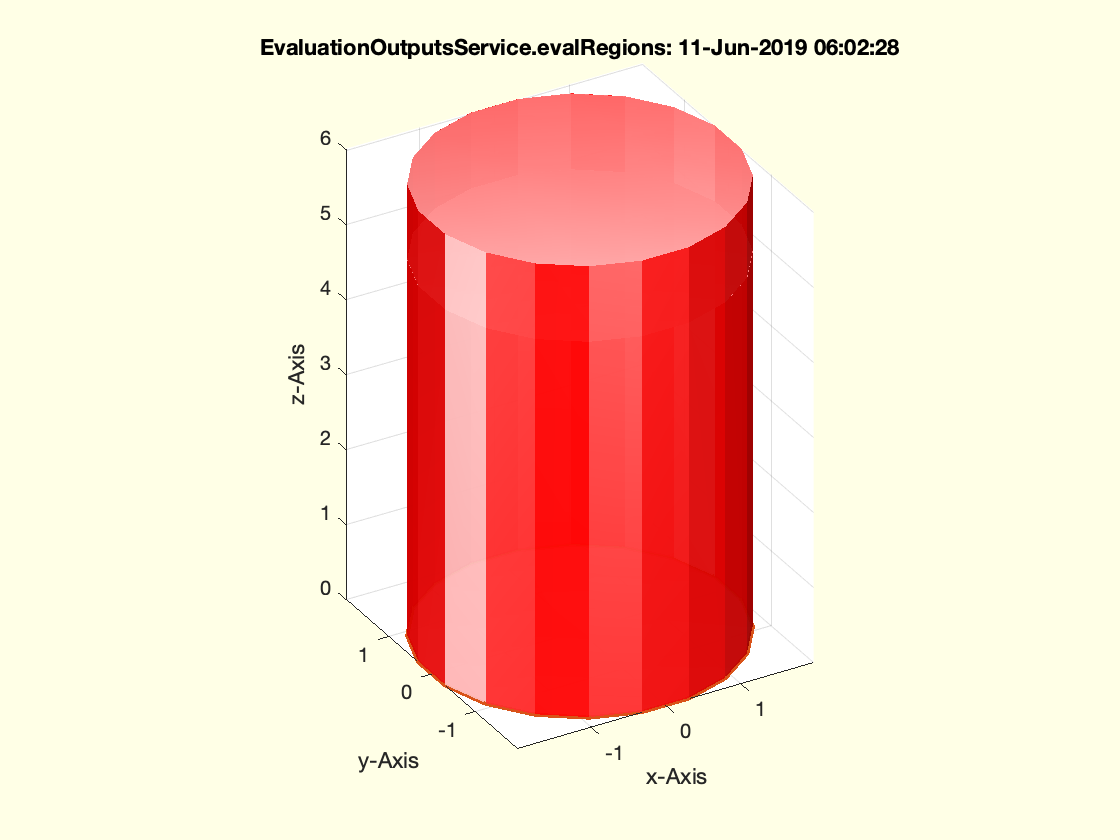


SGofCPLcommand('c 4, h 5, enter, c 4, h 1, rel ontop, cat, check')



ans = struct with fields:
    VL: [80×3 double]
    FL: [152×3 double]
    FC: [152×3 double]


SGofCPLcommand('c 4, h 5, enter, c 4, h 1, rel ontop, cat, check')

#### 4.1.2 Check Geometries outside of SG Coder Language

SGofCPLcommand('c 4, h 5, enter, c 4, h 1, rel ontop, cat'); SG=ans;


SGofCPLcommand('c 4, h 5, enter, c 4, h 1, rel ontop, cat')



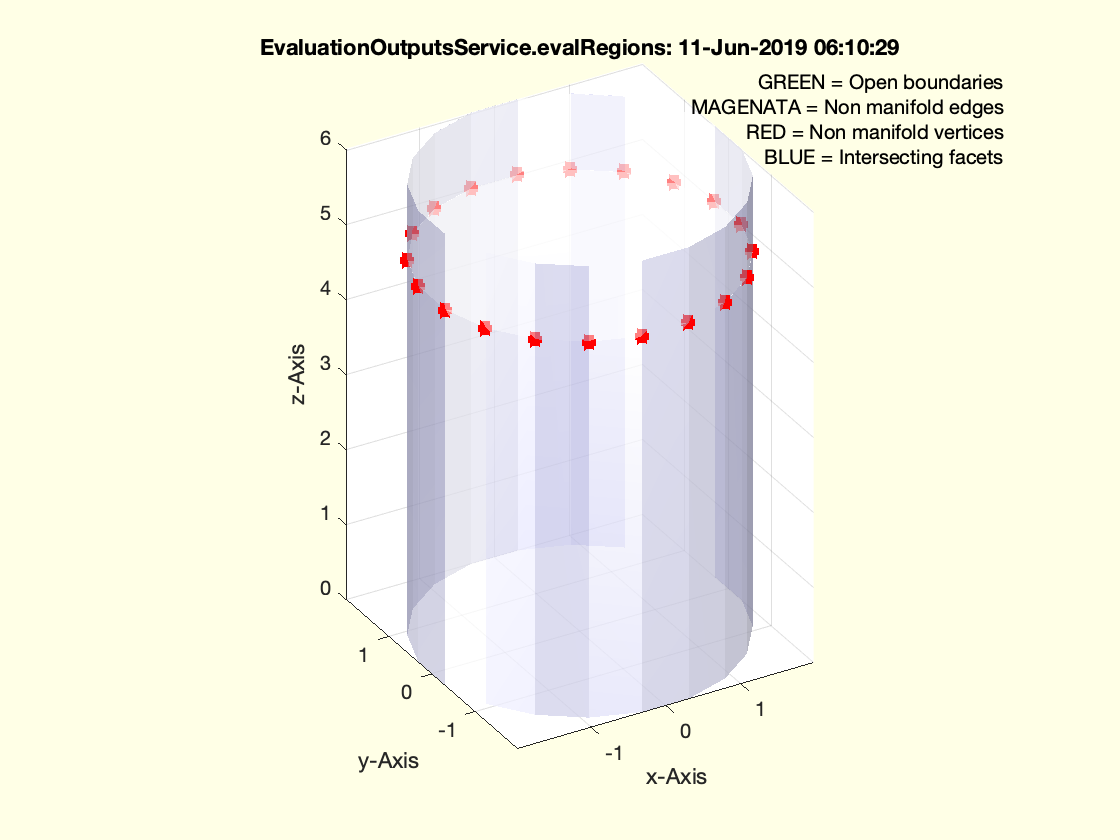


OPEN BOUNDARY:
0 open boundary groups
0 open boundary edges
NON MANIFOLD EGDES:
0 non manifold edges
0 faces over non manifold edges
NON MANIFOLD VERTICES:
2 independent surfaces
20 non manifold vertices
116 faces over non manifold vertices
SELF INTERSECTING FACETS:
too many facets for a self-intersection check


SGcheckmeshlab(SG);

### 4.2 Loading Geometries an Contours from the Workspace

#### 4.2.1 Loading Contours as Closed Polygon Lines from Workspace

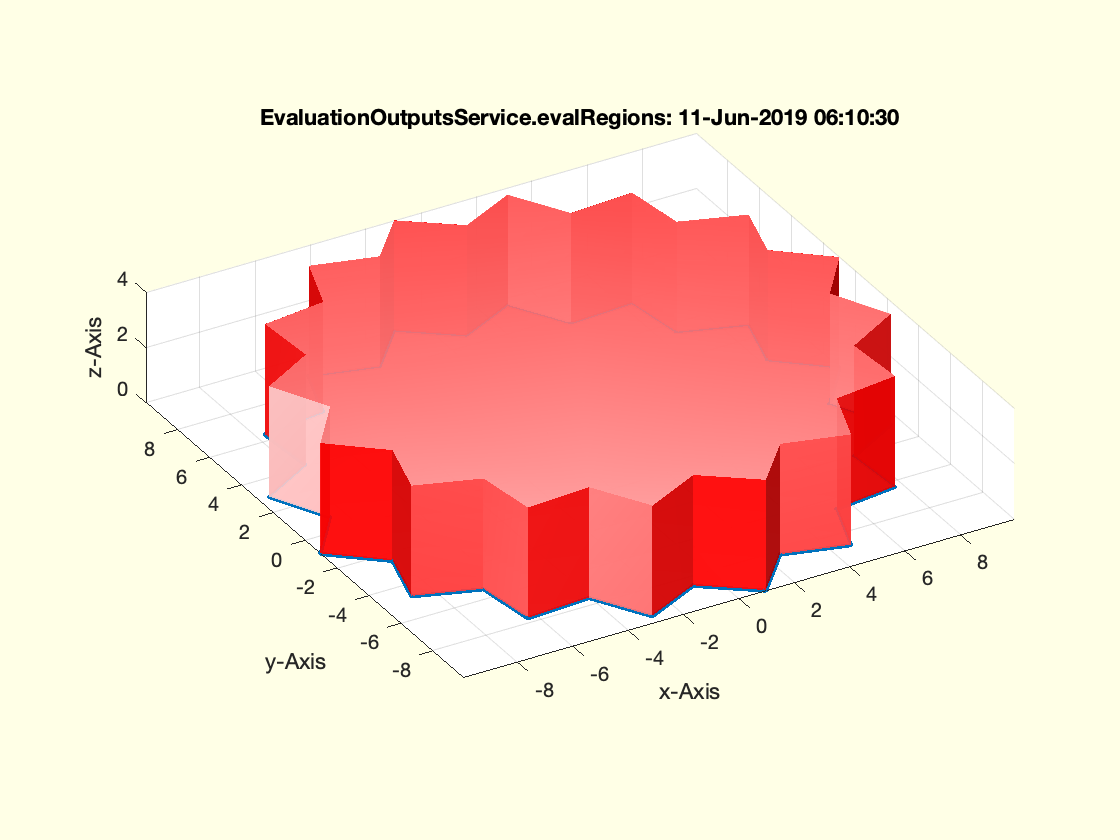


SGofCPLcommand('load A, h 4')



A=PLstar(10);
SGofCPLcommand('load A, h 4'); % Load a Contour

#### 4.2.2 Loading Solid Geometries  from Workspace

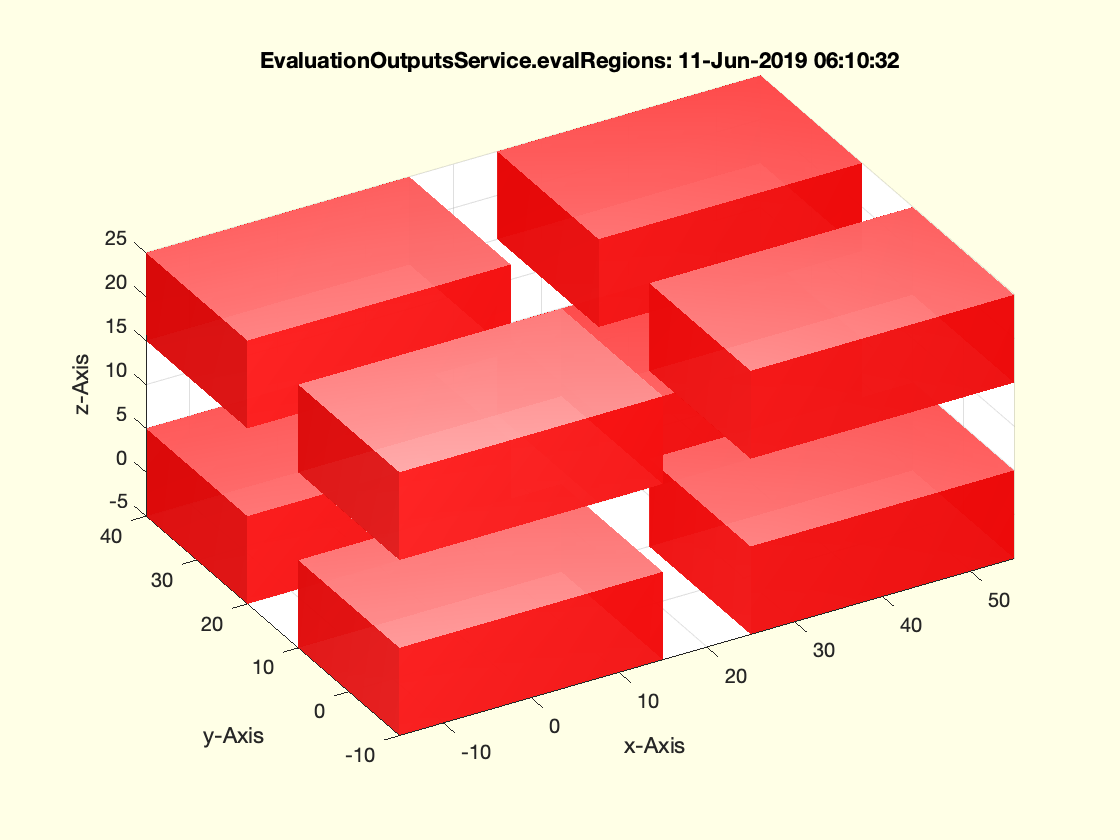


SGofCPLcommand('load A, dups 2 2 2 10')



A=SGbox([30,20,10]); 
SGofCPLcommand('load A, dups 2 2 2 10'); % Load a Solid

### 4.3 Saving Geometries and Contours as Variables in the Workspace

SGofCPLcommand('b 30 20, h 10, c 4, save B'); % Result contains current Solid and CPL


SGofCPLcommand('b 30 20, h 10, c 4, save B')



B, B=B.SG

B = struct with fields:
     SG: [1×1 struct]
    CPL: [20×2 double]


B = struct with fields:
    CPL: [5×2 double]
     VL: [8×3 double]
     FL: [12×3 double]
     PL: [4×2 double]
     EL: [4×2 double]
     FC: [12×3 double]


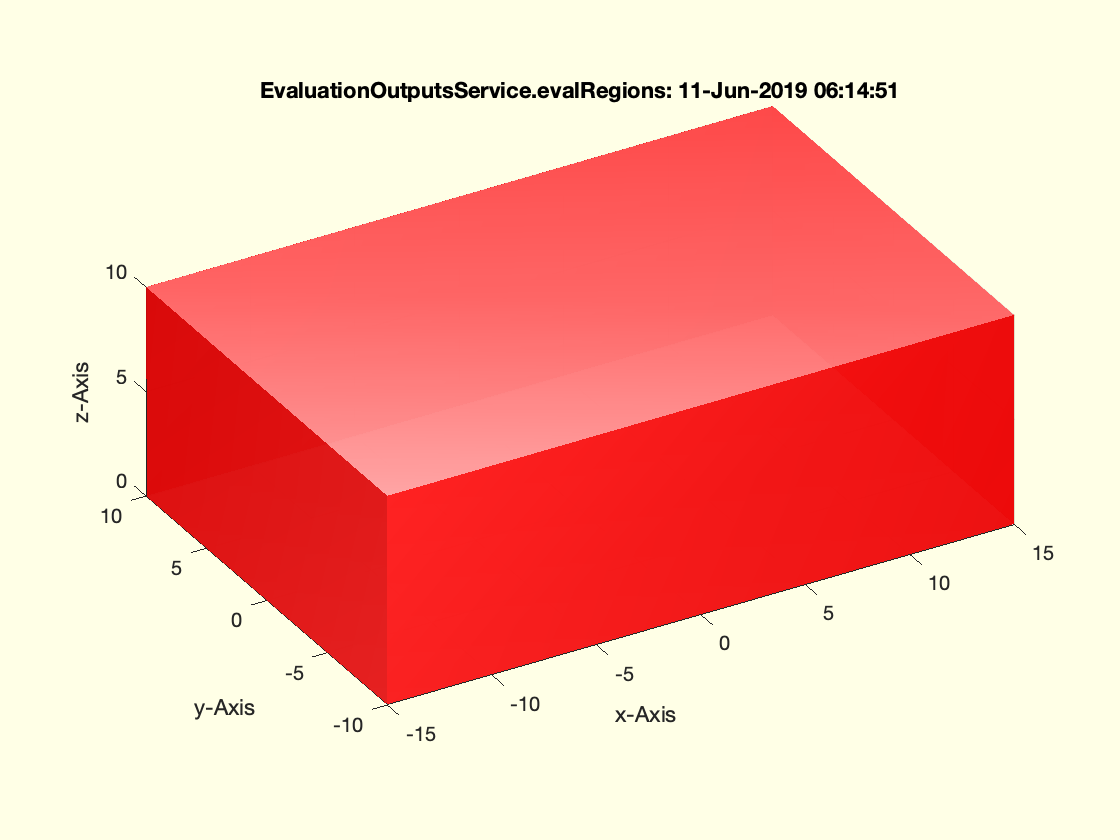


SGofCPLcommand('load B')



SGofCPLcommand('load B'); 

### 4.4 Export byb Writing Solid Geometries as STL Files

ans = '/Users/timlueth/Desktop/B.STL'

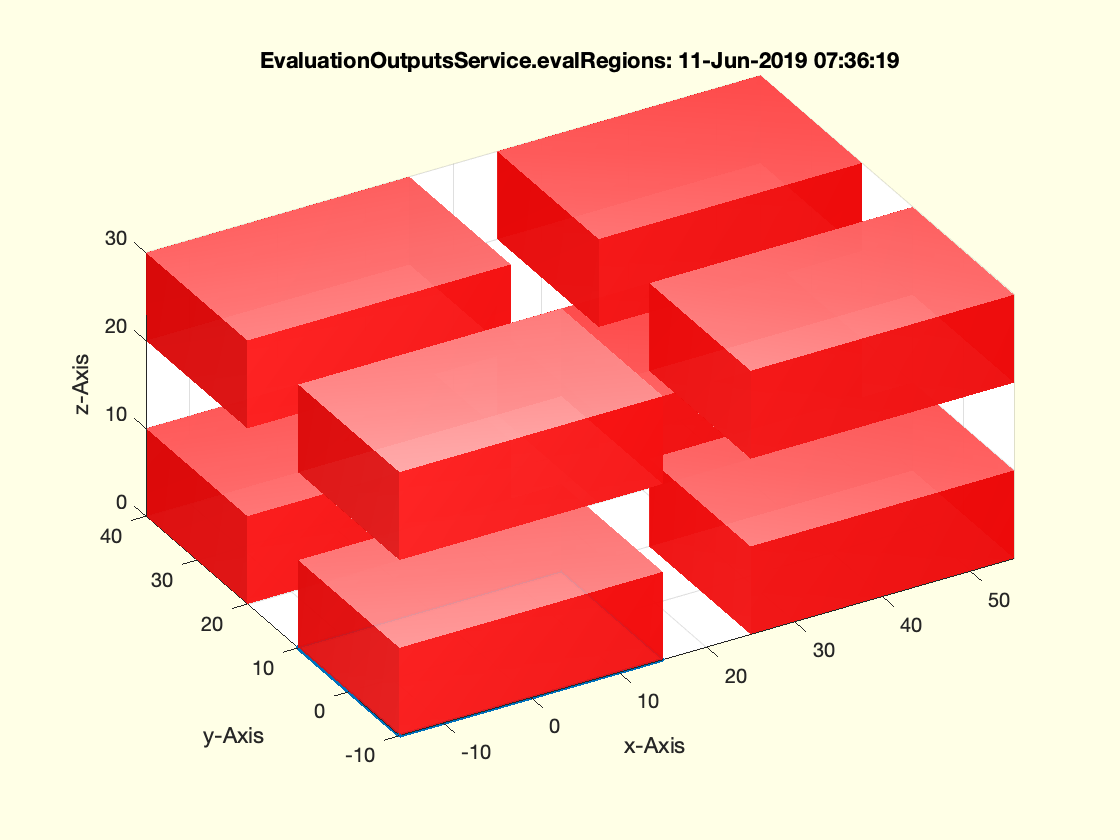


SGofCPLcommand('b 30 20, h 10, dups 2 2 2 10, write B')



SGofCPLcommand('b 30 20, h 10, dups 2 2 2 10, write B');

### 4.4 Import by Reading Solid Geometries in STL Files

ans = '/Users/timlueth/Desktop/B.STL'

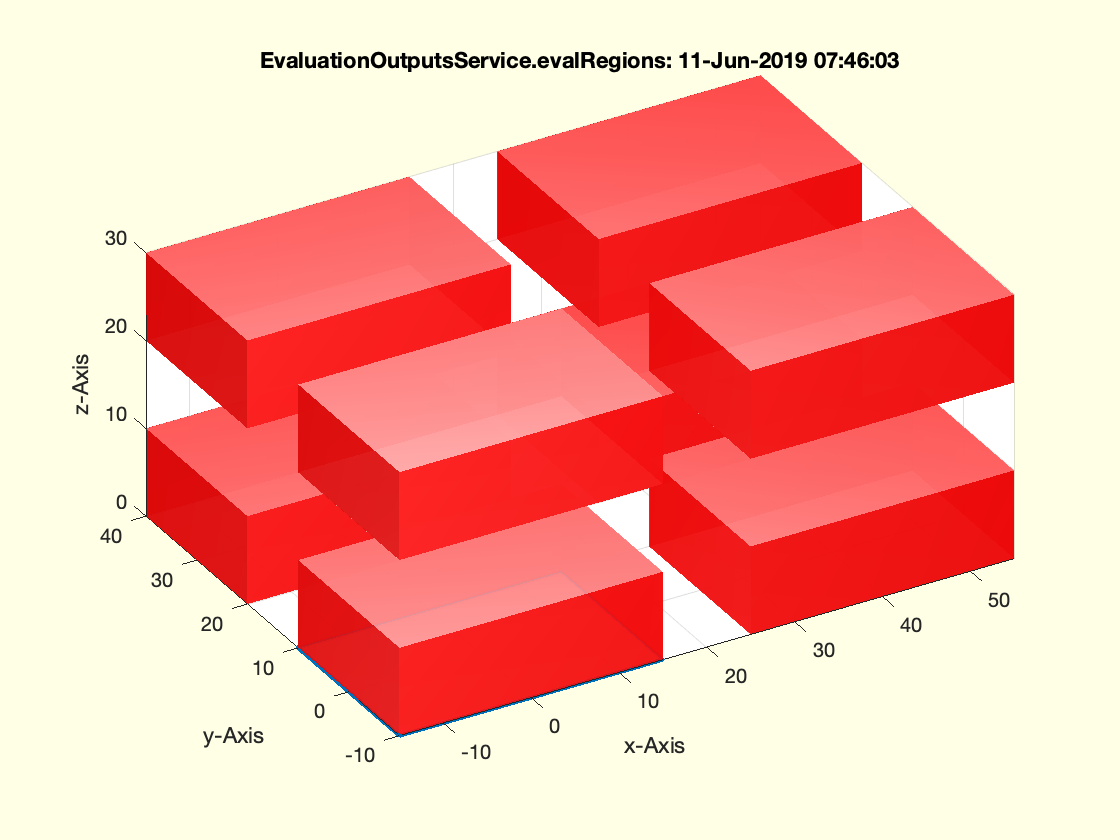


SGofCPLcommand('b 30 20, h 10, dups 2 2 2 10, write B')



SGofCPLcommand('b 30 20, h 10, dups 2 2 2 10, write B');

nam = '/Users/timlueth/Desktop/B.STL'

LOADING BINARY STL-File: /Users/timlueth/Desktop/B.STL
Binary Header: COLOR=RGBA,MATERIAL=AAAABBBBCCCCDDDD;SOLID "B by timlueth" 11-Jun-2019 07:46:03 
Color of solid defined as: "k"
Alpha of solid defined as: 65.00
Number of facets: 96
0..


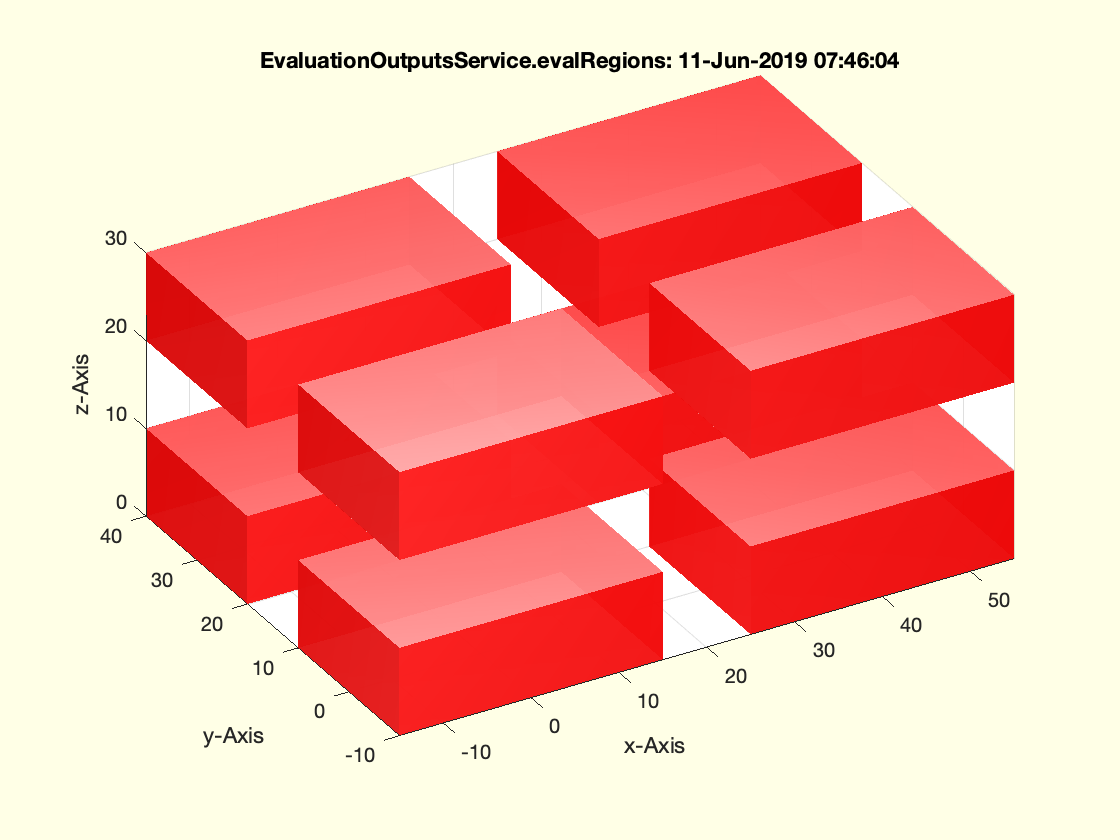


SGofCPLcommand('read B')



SGofCPLcommand('read B');

nam = '/Users/timlueth/Desktop/B.STL'

LOADING BINARY STL-File: /Users/timlueth/Desktop/B.STL
Binary Header: COLOR=RGBA,MATERIAL=AAAABBBBCCCCDDDD;SOLID "B by timlueth" 11-Jun-2019 07:46:03 
Color of solid defined as: "k"
Alpha of solid defined as: 65.00
Number of facets: 96
0..


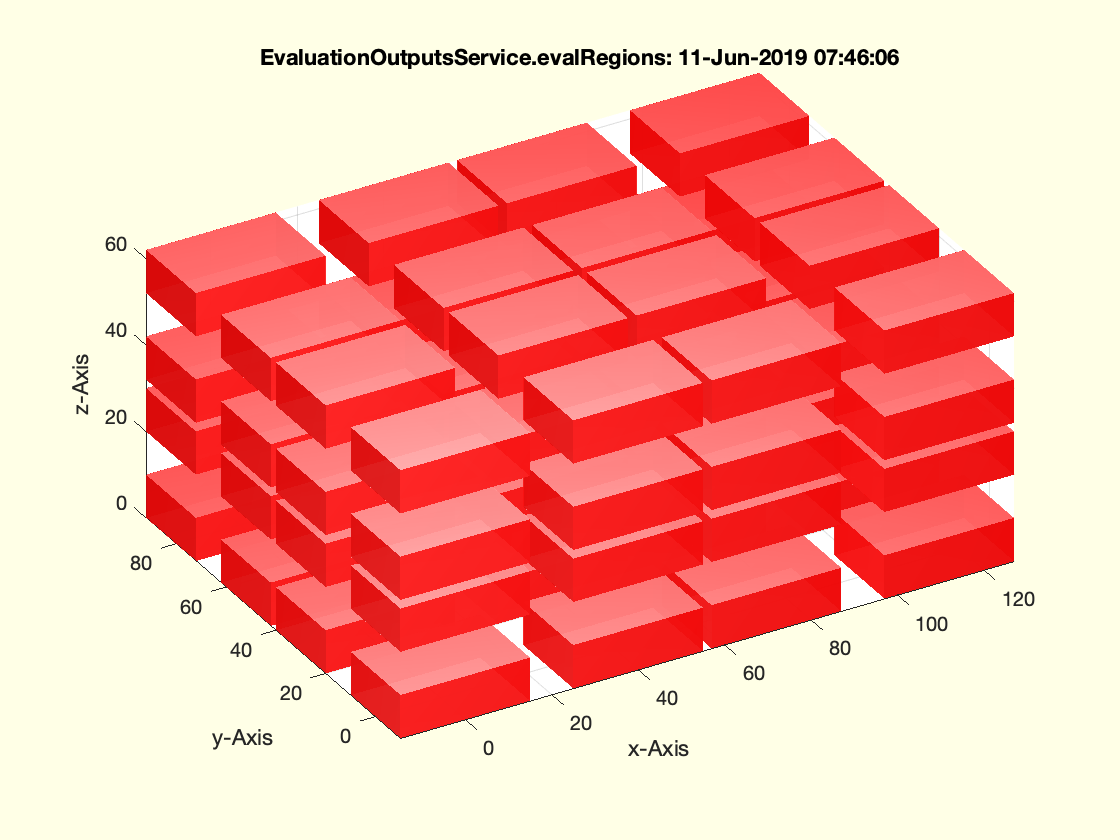


SGofCPLcommand('read B, dups 2 2 2 2')



SGofCPLcommand('read B, dups 2 2 2 2');